# Build Fuzzy Systems at the Command Line

You can construct a fuzzy inference system (FIS) at the MATLAB® command line. This method is an alternative to interactively designing your FIS using [docid:fuzzy.bu9027w](docid:fuzzy.bu9027w).

This example shows you how to create a Mamdani fuzzy inference system. While you create a Mamdani FIS, the methods used apply to creating Sugeno systems as well.

## Tipping Problem at the Command Line

To demonstrate the command-line functionality for creating and viewing fuzzy inference systems, this example uses the tipper FIS. 

fis = readfis('tipper.fis');

This command returns a `mamfis` object that contains the properties of the fuzzy system. For a Sugeno system, this command returns a `sugfis` object.

You can access the FIS properties using dot notation. For example, view the inputs of the fuzzy system.

fis.Inputs

ans =   1×2 fisvar array with properties:

    Name
    Range
    MembershipFunctions

  Details:
           Name        Range     MembershipFunctions
         _________    _______    ___________________

    1    "service"    0    10        {1×3 fismf}    
    2    "food"       0    10        {1×2 fismf}    


To set the properties of your fuzzy system, use dot notation. For example, set the name of the FIS.

fis.Name = "gratuity";

## FIS Object

You represent fuzzy inference systems using [docid:fuzzy#mw_83080bc8-a7f2-45e3-b89a-13bf08fd6f62](docid:fuzzy#mw_83080bc8-a7f2-45e3-b89a-13bf08fd6f62) and [docid:fuzzy#mw_7219a982-c98d-4a71-bd2d-c1d1d8ccfbde](docid:fuzzy#mw_7219a982-c98d-4a71-bd2d-c1d1d8ccfbde) objects. These objects contain all the fuzzy inference system information, including the variable names, membership function definitions, and fuzzy inference methods. Each FIS is itself a hierarchy of objects. The following objects are used within a fuzzy system:

- [docid:fuzzy#mw_40b5c1de-8f3d-4e35-a06f-f9e44f943c35](docid:fuzzy#mw_40b5c1de-8f3d-4e35-a06f-f9e44f943c35) objects represent both input and output variables.

- [docid:fuzzy#mw_35c9a8ef-d038-4570-b473-08f1cf2fd5c5](docid:fuzzy#mw_35c9a8ef-d038-4570-b473-08f1cf2fd5c5) objects represent membership functions within each input and output variable.

- [docid:fuzzy#mw_18bf97aa-b218-4dce-85d6-ba0d1a9ada52](docid:fuzzy#mw_18bf97aa-b218-4dce-85d6-ba0d1a9ada52) objects represent fuzzy rules that map inputs to outputs.

View all the information for a FIS by directly listing its properties.

fis

fis =   mamfis with properties:

                       Name: "gratuity"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×3 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


You can view the properties of the objects within a FIS object using dot notation. For example, view the `fisvar` object for first input variable.

fis.Inputs(1)

ans =   fisvar with properties:

                   Name: "service"
                  Range: [0 10]
    MembershipFunctions: [1×3 fismf]


Also, view the membership functions for this variable.

fis.Inputs(1).MembershipFunctions

ans =   1×3 fismf array with properties:

    Type
    Parameters
    Name

  Details:
            Name          Type       Parameters
         ___________    _________    __________

    1    "poor"         "gaussmf"    1.5      0
    2    "good"         "gaussmf"    1.5      5
    3    "excellent"    "gaussmf"    1.5     10


## System Display Functions

To get a high-level view of your fuzzy system from the command line, use the `plotfis`, `plotmf`, and `gensurf` functions. `plotfis` displays the whole system as a block diagram, as shown in the **Fuzzy Logic Designer**.

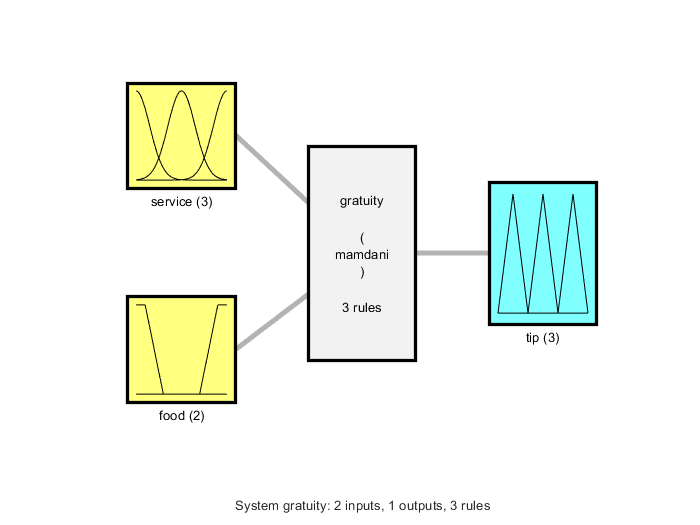

plotfis(fis)

The `plotmf` function plots all the membership functions associated with a given variable. For example, view the membership functions for the first input variable.

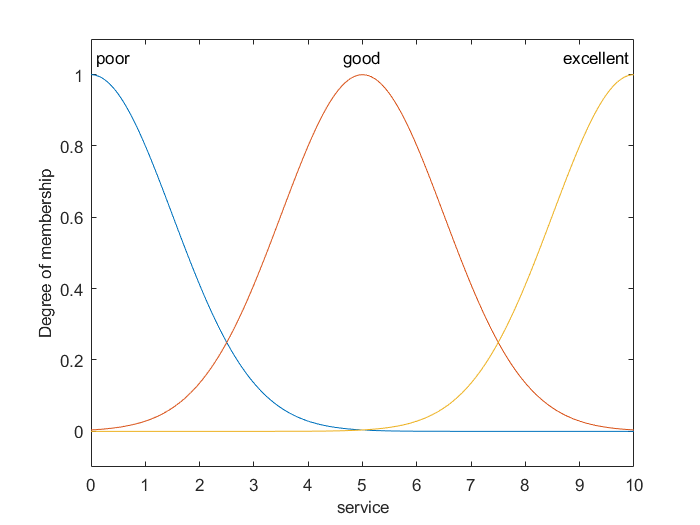

plotmf(fis,'input',1)

Similarly, to view the membership functions for the first output, type:

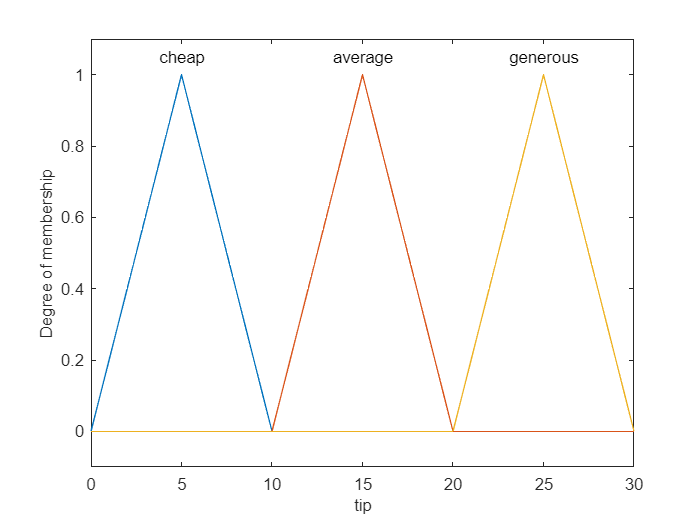

plotmf(fis,'output',1)

`plotmf` does not support viewing the output membership functions for Sugeno systems.

To view the rules of the fuzzy system, type:

fis.Rules

ans =   1×3 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                                Description                        
         __________________________________________________________

    1    "service==poor | food==rancid => tip=cheap (1)"           
    2    "service==good => tip=average (1)"                        
    3    "service==excellent | food==delicious => tip=generous (1)"


The `gensurf` function plots the output of the FIS for any one or two input variables.

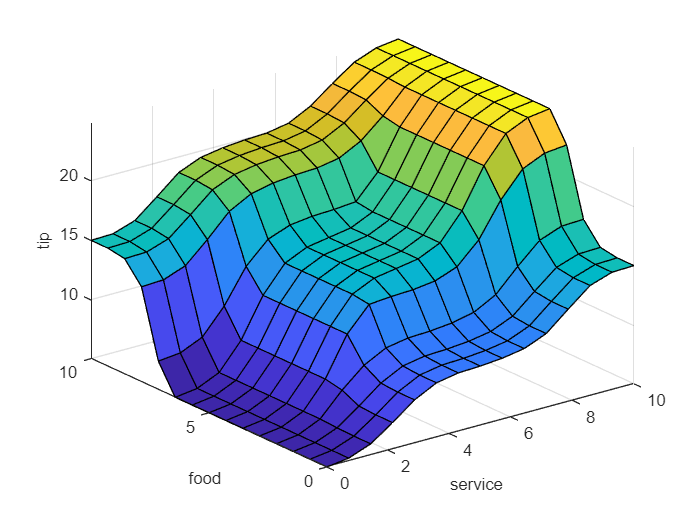

gensurf(fis)

## Build Fuzzy Inference System

As an alternative to using the **Fuzzy Logic Designer** app, you can construct a FIS entirely from the command line.

First, create a Mamdani FIS, specifying its name.

fis = mamfis('Name',"tipper");

Add the first input variable for the service quality using [docid:fuzzy#mw_c87db63b-66a1-416a-95ff-d47c43e0acde](docid:fuzzy#mw_c87db63b-66a1-416a-95ff-d47c43e0acde).

fis = addInput(fis,[0 10],'Name',"service");

Add membership functions for each of the service quality levels using [docid:fuzzy#FP99407](docid:fuzzy#FP99407). In this case, use Gaussian membership functions. For more information on Gaussian membership function properties, see [docid:fuzzy#FP141360](docid:fuzzy#FP141360).

fis = addMF(fis,"service","gaussmf",[1.5 0],'Name',"poor");
fis = addMF(fis,"service","gaussmf",[1.5 5],'Name',"good");
fis = addMF(fis,"service","gaussmf",[1.5 10],'Name',"excellent");

Add the second input variable for the food quality, and add two trapezoidal membership functions. For information on trapezoidal membership functions, see [docid:fuzzy#FP703](docid:fuzzy#FP703).

fis = addInput(fis,[0 10],'Name',"food");
fis = addMF(fis,"food","trapmf",[-2 0 1 3],'Name',"rancid");
fis = addMF(fis,"food","trapmf",[7 9 10 12],'Name',"delicious");

Add the output variable for the tip, and add three triangular membership functions. For more information on the triangular membership function, see [docid:fuzzy#FP715](docid:fuzzy#FP715).

fis = addOutput(fis,[0 30],'Name',"tip");
fis = addMF(fis,"tip","trimf",[0 5 10],'Name',"cheap");
fis = addMF(fis,"tip","trimf",[10 15 20],'Name',"average");
fis = addMF(fis,"tip","trimf",[20 25 30],'Name',"generous");

Specify the following three rules for the FIS as a numeric array:

- If (service is poor) or (food is rancid), then (tip is cheap).

- If (service is good), then (tip is average).

- If (service is excellent) or (food is delicious), then (tip is generous).

Each row of the array contains one rule in the following format.

- Column 1 - Index of membership function for first input

- Column 2 - Index of membership function for second input

- Column 3 - Index of membership function for output

- Column 4 - Rule weight (from `0` to `1`)

- Column 5 - Fuzzy operator (`1` for AND, `2` for OR)

For the membership function indices, indicate a NOT condition using a negative value. For more information on fuzzy rule specification, see [docid:fuzzy#FP40034](docid:fuzzy#FP40034).

ruleList = [1 1 1 1 2;
            2 0 2 1 1;
            3 2 3 1 2];

Add the rules to the FIS.

fis = addRule(fis,ruleList);

Alternatively, you can create the fuzzy inference system using a combination of dot notation and `fisvar`, `fismf`, and `fisrule` objects. This method is not a good practice for most applications. However, you can use this approach when your application requires greater flexibility in constructing and modifying your FIS.

Create the fuzzy inference system.

fis = mamfis('Name','tipper');

Add and configure the first input variable. In this case, create a default `fisvar` object and specify its properties using dot notation.

fis.Inputs(1) = fisvar;
fis.Inputs(1).Name = "service";
fis.Inputs(1).Range = [0 10];

Define the membership functions for the first input variable. For each MF, create a `fismf` object, and set the properties using dot notation.

fis.Inputs(1).MembershipFunctions(1) = fismf;
fis.Inputs(1).MembershipFunctions(1).Name = "poor";
fis.Inputs(1).MembershipFunctions(1).Type = "gaussmf";
fis.Inputs(1).MembershipFunctions(1).Parameters = [1.5 0];
fis.Inputs(1).MembershipFunctions(2) = fismf;
fis.Inputs(1).MembershipFunctions(2).Name = "good";
fis.Inputs(1).MembershipFunctions(2).Type = "gaussmf";
fis.Inputs(1).MembershipFunctions(2).Parameters = [1.5 5];
fis.Inputs(1).MembershipFunctions(3) = fismf;
fis.Inputs(1).MembershipFunctions(3).Name = "excellent";
fis.Inputs(1).MembershipFunctions(3).Type = "gaussmf";
fis.Inputs(1).MembershipFunctions(3).Parameters = [1.5 10];

Add and configure the second input variable. For this variable, specify the name and range when you create the `fisvar` object.

fis.Inputs(2) = fisvar([0 10],'Name',"food");

Specify the membership functions for the second input. For each MF, specify the name, type, and parameters when you create the `fismf` object.

fis.Inputs(2).MembershipFunctions(1) = fismf("trapmf",[-2 0 1 3],...
                                             'Name',"rancid");
fis.Inputs(2).MembershipFunctions(2) = fismf("trapmf",[7 9 10 12],...
                                             'Name',"delicious");

Similarly, add and configure the output variable and its membership functions.

fis.Outputs(1) = fisvar([0 30],'Name',"tip");

In this case, specify the output membership functions using a vector of `fismf` objects.

mf1 = fismf("trimf",[0 5 10],'Name',"cheap");
mf2 = fismf("trimf",[10 15 20],'Name',"average");
mf3 = fismf("trimf",[20 25 30],'Name',"generous");
fis.Outputs(1).MembershipFunctions = [mf1 mf2 mf3];

Create the rules for the fuzzy system. For each rule create a `fisrule` object. Then, specify the rules using a vector of these objects. When creating a `fisrule` object using numeric values, you must specify the number of inputs variables.

rule1 = fisrule([1 1 1 1 2],2);
rule2 = fisrule([2 0 2 1 1],2);
rule3 = fisrule([3 2 3 1 2],2);
rules = [rule1 rule2 rule3];

Before adding your rules to your fuzzy system, you must update them using the data in the FIS object. Update the rules using the `update` function, and add them the fuzzy system.

rules = update(rules,fis);
fis.Rules = rules;

When constructing your fuzzy system, you can also specify custom membership functions and inference functions. For more information, see [docid:fuzzy#brkiiwg-1](docid:fuzzy#brkiiwg-1).

## Evaluate Fuzzy Inference System

To evaluate the output of a fuzzy system for a given input combination, use the [docid:fuzzy#FP312](docid:fuzzy#FP312) command. For example, evaluate `fis` using input variable values of `1` and `2`.

evalfis(fis,[1 2])

ans = 5.5586

You can also evaluate multiple input combinations using an array where each row represents one input combination.

inputs = [3 5;
          2 7;
          3 1];
evalfis(fis,inputs)

ans =    12.2184
    7.7885
    8.9547


*Copyright 2018 The MathWorks, Inc.*